# CS1- 2D interpolation of air pollution

%within CR JANUARY 2000

close all
clear

load('C:\Users\INES\Documents\2DSP Prague\VATI\Data\POLLUTION_PM10');

## 1. Computing day average in every station and their plot

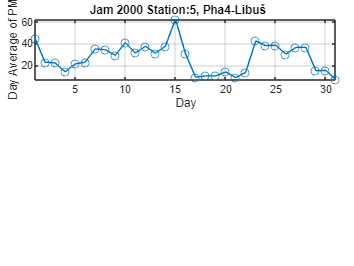

PM = PM10.data;
for d=1:31
    PMday = squeeze(PM(:, :, d)); %new 2D matrix
    average_at_station (:, d)=mean(PMday');
end

figure(1)
station_nb = 5; %station number selection
station_nb_name=PM10.jmena(station_nb, :);

axes('position', [0.1 0.7 0.85 0.23])
plot(average_at_station(station_nb,:), '-o')
grid on, axis tight %for qutomatix x and y limits
xlabel('Day')
ylabel('Day Average of PM')
title(['Jam 2000 Station:', num2str(station_nb), ', ', station_nb_name])

## 2D Interpolation of day average

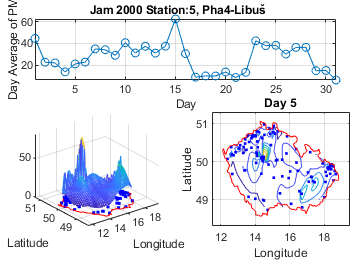

st_latt = PM10.souradnice(:,1);
st_long = PM10.souradnice(:,2);

CR_latt = CR(:, 2);
CR_long = CR(:,1);

day = 5;
% interpolation
[X,Y] = meshgrid([11.5:0.1:19.5],[48.3:0.05:51.3]);
Z = griddata(st_long, st_latt, average_at_station(:, day), X,Y, 'cubic');

% surface plot
axes('position', [0.1 0.15 0.35 0.43])
mesh(X, Y, Z);
grid on
axis([11.5 19.5 48.3 51.3 0 inf]) %inf for infinity

%stations and borders
hold on
plot3(st_long, st_latt, zeros(1, length(st_long)),...
    '.', 'color', 'b', 'markersize', 6)

line(CR_long, CR_latt, zeros(1, length(CR_long)), 'color', 'r')
xlabel('Longitude')
ylabel('Latitude')

% contours
axes('position', [0.6 0.15 0.39 0.43])
contour(X,Y,Z)
grid on
hold on
plot(st_long, st_latt,...
    '.', 'color', 'b', 'markersize', 6)
line(CR_long, CR_latt, 'color', 'r')
xlabel('Longitude')
ylabel('Latitude')
title(['Day ', num2str(day)])


% Movie
f2= figure(2)

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


colormap pink
aviobj = VideoWriter('poll.avi')

aviobj =   VideoWriter

    General Properties:

       Filename:                 'poll.avi'
       Path:                     'C:\Users\INES\Documents\MATLAB'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


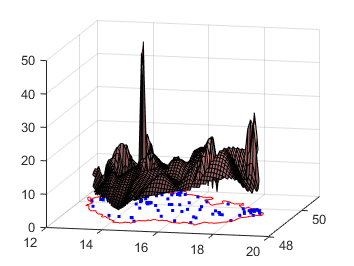

Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


Frame = struct with fields:
       cdata: [420×560×3 uint8]
    colormap: []


open(aviobj)
for day=1:31
    Z = griddata(st_long, st_latt, average_at_station(:, day), X,Y, 'cubic');
    surf(X, Y, Z)
    view(13,14)
    hold on
    plot3(st_long, st_latt, zeros(1, length(st_long)),...
        '.', 'color', 'b', 'markersize', 6)
    
    line(CR_long, CR_latt, zeros(1, length(CR_long)), 'color', 'r')
    Frame = getframe(gcf) %get current figure
    writeVideo(aviobj, Frame)
    
    pause(0.1)
    hold off
end


close(aviobj)